# Color Selector

This widget enables you to have a color selection edit field along with a button that opens a color selection dialog. 

*If you are using R2024a or later, consider if the built-in *[`uicolorpicker`](https://www.mathworks.com/help/matlab/ref/uicolorpicker.html) *meets your needs instead.*

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 45]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

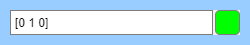

colorWidget = wt.ColorSelector(gridObj);

colorWidget.ValueChangedFcn = @(src,evt)disp(evt)

colorWidget =   ColorSelector with properties:

              Value: [0 1 0]
      ShowEditField: on
    ValueChangedFcn: @(src,evt)disp(evt)
           Position: [11 11 230 25]

  Show all properties


Set a different color value:

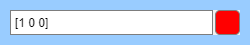

colorWidget.Value = [1 0 0];

If you want to have only the button with no edit field:

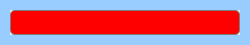

colorWidget.ShowEditField = false;

Make the parent grid column narrower so it appears square:

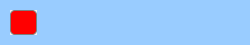

gridObj.ColumnWidth = {27};

*Copyright 2020-2025 The MathWorks, Inc.*